# Vaciado de tanques cilíndricos atmosféricos

Autor: Esteban Gustavo Morales Orellana

Fecha: INGRESE LA FECHA DE ELABORACIÓN DEL PROYECTO

## Resumen

En múltiples industrias, como la alimenticia, química, tratamiento de aguas, entre otras; conocer el tiempo de vaciado de tanques es esencial para mejorar la eficiencia operativa. Este proyecto tiene como objetivo principal determinar el tiempo de vaciado de un tanque cuyas dimensiones proporcione el usuario que tenga acceso al código. El código solución utiliza conceptos como el principio de Torricelli, la ecuaciones de Bernoulli, de Darcy-Weisbach, de Colebrook-White, derivadas e integrales para resolver el problema. El resultado será el tiempo de vaciado con las condiciones proporcionadas.

## Objetivos

- Determinar el tiempo de vaciado de un tanque cilíndrico atmosférico.

- Comprobar si el tanque de diemensiones establecidas se vaciará en más o menos de 24 horas.

## Introducción

El vaciado de tanques cilíndricos atmosféricos es un proceso común en diversas industrias que manejan líquidos, como la química, alimentaria y petroquímica. Estos tanques, al estar expuestos a la presión atmosférica, dependen principalmente de la gravedad para la descarga del fluido. El tiempo de vaciado está influenciado por varios factores, como el diámetro, la altura del tanque, el diámetro de la tubería de salida, la viscosidad del líquido y su densidad. Comprender el comportamiento del vaciado es crucial para optimizar la eficiencia operativa, garantizar la seguridad y mantener la estabilidad de los procesos. A través del análisis de este tiempo, es posible dimensionar correctamente las bombas y válvulas necesarias, evitar tiempos muertos en producción y minimizar el riesgo de sobrellenado o derrames. Si el tiempo de vaciado supera las 24 horas, existen procesos que se pueden llevar a cabo en este tiempo para optimizar recursos. Además, controlar el vaciado permite un mejor aprovechamiento de los recursos, disminuyendo costos energéticos y operativos. Este proceso, aunque en apariencia sencillo, requiere cálculos precisos y la consideración de variables como la fricción en las tuberías y el perfil del fluido. Para este proyecto, se puede elegir entre un procesos "ideal" que no considere pérdidas por fricción o en su defecto, con dichas pérdidas. en el caso de elegir la segunda opción, el código estará programado para desplegar una gráfica comparando ambos procesos.

## Datos

    Dimensiones del tanque

        REQUERIMIENTO: la razón de la altura y el diámetro del tanque debe encontrarse en el intervalo [1.5 - 2.0]

h = input("Ingrese el valor de la altura del tanque en [m]: ");   
D = input("Ingrese el valor del diámetro del tanque en [m]: ");        
d = input("Ingrese el valor del diámetro de la descarga en [m]: ");    
g = 9.81;                                                            % gravedad [m/s2]
reqdim = h/D;                                                        % Requerimiento del dimensionamiento del tanque
while reqdim < 1.5 || reqdim > 2
      disp("Los valores ingresados de altura y diámetro de tanque no cumplen el dimensionamiento");
      h = input("Ingrese el valor de la altura del tanque: ");
      D = input("Ingrese el valor del diámetro del tanque: ");
      reqdim = h/D;
      if reqdim >= 1.5 && reqdim <= 2
          break
      end
end

## Código solución

AT = (pi/4)*D^2;                                         % Área transversal del tanque [m2]
at = (pi/4)*d^2;                                         % Área transversal tubería de descarga [m2]

¿Sistema con o sin pérdidas por fricción?

perdidas = menu("¿Desea que su sistema considere pérdidas friccionales?", "Sí", "No");
if perdidas == 2
    hl = h*0.875;                                            % Altura del líquido, se corrige con principios de dimensionamiento
    hg = linspace(hl,0);                                     % Vector de la altura, empieza en hl y termina en 0, para la gráfica
    tv = (AT/at)*2*((hg(1)^0.5)-(hg.^0.5))./((2*g)^0.5);     % Vector de tiempo de vaciado [s] en función de la altura
    t = tv./3600;                                            % Vector tiempo de vaciado [horas]
    T = tv(100)/3600;                                        % Tiempo de vaciado [horas]
    plot(t,hg);                                              % Gráfica altura [m] vs. tiempo [s]
    xlabel("tiempo [h]")
    ylabel("altura del líquido [m]")
    xline(24, "DisplayName", "24 horas");
    title("Tiempo de vaciado de tanque cilíndrico atmosférico")
    subtitle("Altura vs. tiempo (sin pérdidas)")
else
    delta = input("Ingrese la densidad de su fluido en [kg/m3]: ");
    vis = input("Ingrese la viscosidad de su fluido en [kg/m*s]: ");
    L = input("Ingrese la longitud de la tubería de descarga [m]: ");

Ya que el número de Reynolds depende directamente de la velocidad del fluido, la misma que depende de la altura del fluido a medida que se descarga; y el factor de fricción depende del número de Reynolds,  se asumirá un valor de 2 m/s, una velocidad dada por una tubería de proceso.

    Vasum = 2;                                               % Velocidad de descarga asumida [m/s]
    Re = delta*d*Vasum/vis;                                  % Número de Reynolds [adimensional]
    if Re <= 2100                                            % Flujo laminar; Re no depende del material, solo del fluido
        freal = 64/Re;
    else
        material = menu("Elija el material de la tubería","Vidrio o plástico","Madera", "Goma","Cobre","Hiero fundido","Hierro galvanizado","Hierro forjado","Acero inoxidable","Acero comercial");
        switch material
            case 1
            e = 0;                                                           % Rugosidad del material [mm]
            case 2
            e = 0.5;
            case 3
            e = 0.01;
            case 4
            e = 0.0015;
            case 5
            e = 0.26;
            case 6
            e = 0.15;
            case 7
            e = 0.046;
            case 8
            e = 0.002;
            case 9
            e = 0.045;
        end
    efinal = e/1000;                                                         % Rugosidad del material [m]
    f = @(z) -2*log10((efinal/(3.7*d))+(2.51./(Re*z.^0.5)))-(1./z.^0.5);

Búsqueda de un valor inicial

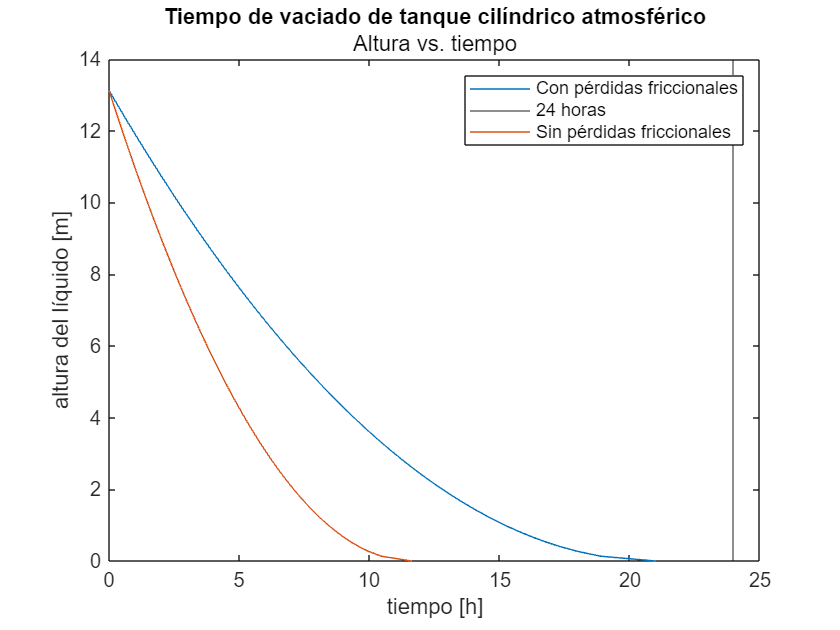

    f_valores_posibles = linspace(0.008, 0.1, 1000);                         % Valor mínimo y máximo que puede ser el factor de fricción de acuerdo al diagrama de Moody
    x = f(f_valores_posibles);                                               % Evaluación de la función anónima con cada valor del vector de valores posibles
    n = 1;
    while x(n)>= 0.1 || x(n)<= -0.1                                          % Bucle hasta encontrar el valor más proximo a cero del vector x para así obtener una buena aproximación del valor inicial
        n = n+1;
        if n == 1000
            break
        end
    end
    f0 = f_valores_posibles(n);                                              % Valor inicial
    freal = fzero(f,f0);                                                     % Valor real
    end
    hl = h*0.875;                                                            % Altura del líquido, se corrige con principios de dimensionamiento
    hg = linspace(hl,0);                                                     % Vector de la altura, empieza en hl y termina en 0, para la gráfica
    tv = (AT/at)*2*((hg(1)^0.5)-(hg.^0.5))./((2*g/(1+(freal*L/d)))^0.5);     % Vector de tiempo de vaciado [s] en función de la altura considerando las pérdidas por fricción
    t = tv./3600;                                                            % Vector tiempo de vaciado [horas]
    tv_1 = (AT/at)*2*((hg(1)^0.5)-(hg.^0.5))./(2*g)^0.5;                     % Vector de tiempo de vaciado [s] en función de la altura sin considerar las pérdidas por fricción
    T = tv_1(100)/3600;                                                      % Tiempo de vaciado [horas]
    t_1 = tv_1./3600;                                                        % Vector tiempo de vaciado [horas]
    T_1 = tv_1(100)/3600;                                                    % Tiempo de vaciado [horas]
    plot(t,hg,"DisplayName", "Con pérdidas friccionales");
    xlabel("tiempo [h]")
    ylabel("altura del líquido [m]")
    xline(24, "DisplayName", "24 horas");
    title("Tiempo de vaciado de tanque cilíndrico atmosférico")
    subtitle("Altura vs. tiempo")
    hold on
    plot(t_1,hg,"DisplayName", "Sin pérdidas friccionales");
    legend
    hold off
end

## Resultado

fprintf("Un tanque de altura %.2f m, diámetro %.2f m y diámetro de tubería de salida de %.3f m, cuyo fluido está a %.2f m, se vaciará en %.5f horas.",h,D,d,hl,T)

Un tanque de altura 15.00 m, diámetro 8.00 m y diámetro de tubería de salida de 0.050 m, cuyo fluido está a 13.12 m, se vaciará en 11.63235 horas.

## Referencias

Ingresar las referencias empleadas para la realización del proyecto. Puede incluir libros, páginas web y artículos. Asegúrese que las referencias sean hipervínculos.

- [Modelo matemático para vaciado de tanques](https://www.redalyc.org/pdf/849/84953102012.pdf)

- [Modelo matemático en ingeniería. Vaciado de tanques](https://d1wqtxts1xzle7.cloudfront.net/50634020/VACIADO_DE_TANQUE_-_MEDELLIN-_MAYO_2014-libre.pdf?1480511380=&response-content-disposition=inline%3B+filename%3DModelamiento_Matematico_en_Ingenieria_Va.pdf&Expires=1728358996&Signature=KjHPoTSfpC5sqHLuo1U9hTnTKt30L3CRE4ra2CQA4ZtNAXYhlH5Cb1fiMvEUXUztKebuJTMNtMhH7QqMPMjTMzCFowYpLMaqjPflTxPz~v~xvHAskJlxA-ikL-M6hOvrpeVfvd8F4Opgdr-hY34K0hMJL34Tji-I9xPb5e-BkapwyVSBZL-H2rONao5p-x6Lrdv1~Vc~KCkdzfVnfqNmJmfHY333r0Gyl7cwpBVoAesogzfajhd60jnwDWQygeM4fMhyBM3cTD2IOgMwnTWSwgIgAj5C5BGjLZ6wnJY8I1PSPjBBLjK-x9vGyhvrTFLdBjSTVbkGk4ksevzulYaArg__&Key-Pair-Id=APKAJLOHF5GGSLRBV4ZA)

- [Aplicación del teorema de Torricelli](file:///C:/Users/Usuario/Downloads/Dialnet-AplicacionDelTeoremaDeTorricelli-9696893.pdf)